# Two Link Planar Robot Manipulator with massless links

## Clear all data

clc;
clear all;
close all;
clf; %Clear all figures

## Basic Definition

bar_mass = [1; 1]; % mass of bar in kg
bar_length = [1; 1]; %Length of bar in m
center_of_mass  = [1; 1];
moment_of_inertia = [0; 0];
initial_parameters = [30; 0; 45; 0]; % Initial degree (theta1, theta_dot_1, theta2, theta_dot_2) parameters of bar
initial_parameters = [deg2rad(initial_parameters(1,1)); deg2rad(initial_parameters(2,1)); deg2rad(initial_parameters(3,1)); deg2rad(initial_parameters(4,1))]; % Initial degree (thetha, thetha_dot) parameters of bar
applied_torque = [0; 0]; % Applied torque to the bar (T) 
% where T is applied wrt to +ve x axis
gravitational_acceleration = 9.8; %m/s2
graph_time = 10; % Time frame for plotting

## Symbolic Definition

syms g m1 m2 h1 h2 v1 v2 I1 I2 w1 w2 l1 l2 r1 r2 x1(t) x2(t) y1(t) y2(t) theta1(t) theta2(t) T1 T2 'real' % Creating Symbolic Variables

sympref('AbbreviateOutput',false);
sympref('MatrixWithSquareBrackets',true);
sympref('PolynomialDisplayStyle','ascend');

## Define Generalised Coordinates

q = sym('q',[2,1]);
q(1) = theta1;
q(2) = theta2;
q

$$q = \left[\begin{array}{c} \theta_{1}\left(t\right)\\ \theta_{2}\left(t\right) \end{array}\right]$$

dq = diff(q,t)

$$dq = \left[\begin{array}{c} \frac{\partial }{\partial t}\theta_{1}\left(t\right)\\ \frac{\partial }{\partial t}\theta_{2}\left(t\right) \end{array}\right]$$

## Defining Generalised Inputs

u = sym('u',[2,1]);
u(1) = T1;
u(2) = T2;
u

$$u = \left[\begin{array}{c} T_{1}\\ T_{2} \end{array}\right]$$

## Derive Lagrangian Function

PE = m1*g*h1 + m2*g*h2;
PE = subs(PE,[h1, h2],[r1*sin(theta1), l1*sin(theta1) + r2*sin(theta1 + theta2)])

$$PE = \left(\sin\left(\theta_{1}\left(t\right)+\theta_{2}\left(t\right)\right)\,r_{2}+\sin\left(\theta_{1}\left(t\right)\right)\,l_{1}\right)\,g\,m_{2}+\sin\left(\theta_{1}\left(t\right)\right)\,g\,m_{1}\,r_{1}$$

KE = (m1*(v1^2)/2) + (I1*(w1^2)/2) + (m2*(v2^2)/2) + (I2*(w2^2)/2);
KE = subs(KE,[v1, v2],[sqrt(diff(x1,t)^2 + diff(y1,t)^2), sqrt(diff(x2,t)^2 + diff(y2,t)^2)]);
KE = subs(KE,[x1,y1,w1,x2,y2,w2],[r1*cos(theta1), r1*sin(theta1), diff(theta1,t), l1*cos(theta1) + r2*cos(theta1 + theta2), l1*sin(theta1) + r2*sin(theta1 + theta2),diff(theta2,t)])

$$KE = \frac{m_{2}\,\left({\left(r_{2}\,\cos\left(\theta_{1}\left(t\right)+\theta_{2}\left(t\right)\right)\,\left(\frac{\partial }{\partial t}\theta_{1}\left(t\right)+\frac{\partial }{\partial t}\theta_{2}\left(t\right)\right)+l_{1}\,\cos\left(\theta_{1}\left(t\right)\right)\,\frac{\partial }{\partial t}\theta_{1}\left(t\right)\right)}^{2}+{\left(r_{2}\,\sin\left(\theta_{1}\left(t\right)+\theta_{2}\left(t\right)\right)\,\left(\frac{\partial }{\partial t}\theta_{1}\left(t\right)+\frac{\partial }{\partial t}\theta_{2}\left(t\right)\right)+l_{1}\,\sin\left(\theta_{1}\left(t\right)\right)\,\frac{\partial }{\partial t}\theta_{1}\left(t\right)\right)}^{2}\right)}{2}+\frac{m_{1}\,\left({r_{1}}^{2}\,{\sin\left(\theta_{1}\left(t\right)\right)}^{2}\,{\left(\frac{\partial }{\partial t}\theta_{1}\left(t\right)\right)}^{2}+{r_{1}}^{2}\,{\cos\left(\theta_{1}\left(t\right)\right)}^{2}\,{\left(\frac{\partial }{\partial t}\theta_{1}\left(t\right)\right)}^{2}\right)}{2}+\frac{I_{1}\,{\left(\frac{\partial }{\partial t}\theta_{1}\left(t\right)\right)}^{2}}{2}+\frac{I_{2}\,{\left(\frac{\partial }{\partial t}\theta_{2}\left(t\right)\right)}^{2}}{2}$$

LE = KE - PE;
LE = simplify(LE)

$$LE = \frac{I_{1}\,{\left(\frac{\partial }{\partial t}\theta_{1}\left(t\right)\right)}^{2}}{2}+\frac{I_{2}\,{\left(\frac{\partial }{\partial t}\theta_{2}\left(t\right)\right)}^{2}}{2}+\frac{{l_{1}}^{2}\,m_{2}\,{\left(\frac{\partial }{\partial t}\theta_{1}\left(t\right)\right)}^{2}}{2}+\frac{m_{1}\,{r_{1}}^{2}\,{\left(\frac{\partial }{\partial t}\theta_{1}\left(t\right)\right)}^{2}}{2}+\frac{m_{2}\,{r_{2}}^{2}\,{\left(\frac{\partial }{\partial t}\theta_{1}\left(t\right)\right)}^{2}}{2}+\frac{m_{2}\,{r_{2}}^{2}\,{\left(\frac{\partial }{\partial t}\theta_{2}\left(t\right)\right)}^{2}}{2}-g\,m_{1}\,r_{1}\,\sin\left(\theta_{1}\left(t\right)\right)+m_{2}\,{r_{2}}^{2}\,\frac{\partial }{\partial t}\theta_{2}\left(t\right)\,\frac{\partial }{\partial t}\theta_{1}\left(t\right)-g\,m_{2}\,r_{2}\,\sin\left(\theta_{1}\left(t\right)+\theta_{2}\left(t\right)\right)-g\,l_{1}\,m_{2}\,\sin\left(\theta_{1}\left(t\right)\right)+l_{1}\,m_{2}\,r_{2}\,\cos\left(\theta_{2}\left(t\right)\right)\,{\left(\frac{\partial }{\partial t}\theta_{1}\left(t\right)\right)}^{2}+l_{1}\,m_{2}\,r_{2}\,\cos\left(\theta_{2}\left(t\right)\right)\,\frac{\partial }{\partial t}\theta_{2}\left(t\right)\,\frac{\partial }{\partial t}\theta_{1}\left(t\right)$$

## Derive Euler Lagrangian Equations

dLE_dq = jacobian(LE,q);
dLE_ddq = jacobian(KE,dq);
d_dLE_dtDdq = diff(dLE_ddq,t);
EU_eq1 = d_dLE_dtDdq(1,1) - dLE_dq(1,1) - u(1);
EU_eq2 = d_dLE_dtDdq(1,2) - dLE_dq(1,2) - u(2);
EU_eq1 = simplify(EU_eq1);
EU_eq2 = simplify(EU_eq2);
syms thetha1 thethadot1 thethaddot1 thetha2 thethadot2 thethaddot2 'real'
EU_eq1 = subs(EU_eq1,[theta1, diff(theta1,t), diff(theta1,t,2), theta2, diff(theta2,t), diff(theta2,t,2)],[thetha1, thethadot1, thethaddot1, thetha2, thethadot2, thethaddot2])

$$EU\_eq1 = I_{1}\,{\mathrm{thethaddot}}_{1}-T_{1}+{l_{1}}^{2}\,m_{2}\,{\mathrm{thethaddot}}_{1}+m_{1}\,{r_{1}}^{2}\,{\mathrm{thethaddot}}_{1}+m_{2}\,{r_{2}}^{2}\,{\mathrm{thethaddot}}_{1}+m_{2}\,{r_{2}}^{2}\,{\mathrm{thethaddot}}_{2}+g\,m_{2}\,r_{2}\,\cos\left({\mathrm{thetha}}_{2}+{\mathrm{thetha}}_{1}\right)+g\,l_{1}\,m_{2}\,\cos\left({\mathrm{thetha}}_{1}\right)+g\,m_{1}\,r_{1}\,\cos\left({\mathrm{thetha}}_{1}\right)-l_{1}\,m_{2}\,r_{2}\,{{\mathrm{thethadot}}_{2}}^{2}\,\sin\left({\mathrm{thetha}}_{2}\right)+2\,l_{1}\,m_{2}\,r_{2}\,{\mathrm{thethaddot}}_{1}\,\cos\left({\mathrm{thetha}}_{2}\right)+l_{1}\,m_{2}\,r_{2}\,{\mathrm{thethaddot}}_{2}\,\cos\left({\mathrm{thetha}}_{2}\right)-2\,l_{1}\,m_{2}\,r_{2}\,{\mathrm{thethadot}}_{1}\,{\mathrm{thethadot}}_{2}\,\sin\left({\mathrm{thetha}}_{2}\right)$$

EU_eq2 = subs(EU_eq2,[theta1, diff(theta1,t), diff(theta1,t,2), theta2, diff(theta2,t), diff(theta2,t,2)],[thetha1, thethadot1, thethaddot1, thetha2, thethadot2, thethaddot2])

$$EU\_eq2 = I_{2}\,{\mathrm{thethaddot}}_{2}-T_{2}+m_{2}\,{r_{2}}^{2}\,{\mathrm{thethaddot}}_{1}+m_{2}\,{r_{2}}^{2}\,{\mathrm{thethaddot}}_{2}+g\,m_{2}\,r_{2}\,\cos\left({\mathrm{thetha}}_{2}+{\mathrm{thetha}}_{1}\right)+l_{1}\,m_{2}\,r_{2}\,{{\mathrm{thethadot}}_{1}}^{2}\,\sin\left({\mathrm{thetha}}_{2}\right)+l_{1}\,m_{2}\,r_{2}\,{\mathrm{thethaddot}}_{1}\,\cos\left({\mathrm{thetha}}_{2}\right)$$

## Symbolic Solution to EL Equation

[thethaddot1, thethaddot2]=solve([EU_eq1, EU_eq2],[thethaddot1, thethaddot2])

$$thethaddot1 = \frac{I_{2}\,T_{1}+T_{1}\,m_{2}\,{r_{2}}^{2}-T_{2}\,m_{2}\,{r_{2}}^{2}+l_{1}\,{m_{2}}^{2}\,{r_{2}}^{3}\,{{\mathrm{thethadot}}_{1}}^{2}\,\sin\left({\mathrm{thetha}}_{2}\right)+l_{1}\,{m_{2}}^{2}\,{r_{2}}^{3}\,{{\mathrm{thethadot}}_{2}}^{2}\,\sin\left({\mathrm{thetha}}_{2}\right)-I_{2}\,g\,m_{2}\,r_{2}\,\cos\left({\mathrm{thetha}}_{2}+{\mathrm{thetha}}_{1}\right)-g\,l_{1}\,{m_{2}}^{2}\,{r_{2}}^{2}\,\cos\left({\mathrm{thetha}}_{1}\right)-I_{2}\,g\,l_{1}\,m_{2}\,\cos\left({\mathrm{thetha}}_{1}\right)-I_{2}\,g\,m_{1}\,r_{1}\,\cos\left({\mathrm{thetha}}_{1}\right)-T_{2}\,l_{1}\,m_{2}\,r_{2}\,\cos\left({\mathrm{thetha}}_{2}\right)+2\,l_{1}\,{m_{2}}^{2}\,{r_{2}}^{3}\,{\mathrm{thethadot}}_{1}\,{\mathrm{thethadot}}_{2}\,\sin\left({\mathrm{thetha}}_{2}\right)+g\,l_{1}\,{m_{2}}^{2}\,{r_{2}}^{2}\,\cos\left({\mathrm{thetha}}_{2}+{\mathrm{thetha}}_{1}\right)\,\cos\left({\mathrm{thetha}}_{2}\right)+{l_{1}}^{2}\,{m_{2}}^{2}\,{r_{2}}^{2}\,{{\mathrm{thethadot}}_{1}}^{2}\,\cos\left({\mathrm{thetha}}_{2}\right)\,\sin\left({\mathrm{thetha}}_{2}\right)+I_{2}\,l_{1}\,m_{2}\,r_{2}\,{{\mathrm{thethadot}}_{2}}^{2}\,\sin\left({\mathrm{thetha}}_{2}\right)-g\,m_{1}\,m_{2}\,r_{1}\,{r_{2}}^{2}\,\cos\left({\mathrm{thetha}}_{1}\right)+2\,I_{2}\,l_{1}\,m_{2}\,r_{2}\,{\mathrm{thethadot}}_{1}\,{\mathrm{thethadot}}_{2}\,\sin\left({\mathrm{thetha}}_{2}\right)}{I_{1}\,I_{2}+{l_{1}}^{2}\,{m_{2}}^{2}\,{r_{2}}^{2}+I_{2}\,{l_{1}}^{2}\,m_{2}+I_{2}\,m_{1}\,{r_{1}}^{2}+I_{1}\,m_{2}\,{r_{2}}^{2}+I_{2}\,m_{2}\,{r_{2}}^{2}-{l_{1}}^{2}\,{m_{2}}^{2}\,{r_{2}}^{2}\,{\cos\left({\mathrm{thetha}}_{2}\right)}^{2}+m_{1}\,m_{2}\,{r_{1}}^{2}\,{r_{2}}^{2}+2\,I_{2}\,l_{1}\,m_{2}\,r_{2}\,\cos\left({\mathrm{thetha}}_{2}\right)}$$

## Defining State Space Matrix

%x = sym('X',[4,1]); %Create a 4X1 State Space Matrix Vector
%x(1) = phi1;
%x(2) = phi_dot_1;
%x(3) = phi2;
%x(3) = phi_dot_2;
%x
thethaddot1 = subs(thethaddot1,[g, T1, m1, l1, r1, I1, T2, m2, l2, r2, I2],[gravitational_acceleration, applied_torque(1,1), bar_mass(1,1), bar_length(1,1), center_of_mass(1,1), moment_of_inertia(1,1), applied_torque(2,1), bar_mass(2,1), bar_length(2,1), center_of_mass(2,1), moment_of_inertia(2,1)])

$$thethaddot1 = -\frac{{{\mathrm{thethadot}}_{1}}^{2}\,\sin\left({\mathrm{thetha}}_{2}\right)-\frac{98\,\cos\left({\mathrm{thetha}}_{1}\right)}{5}+{{\mathrm{thethadot}}_{2}}^{2}\,\sin\left({\mathrm{thetha}}_{2}\right)+\frac{49\,\cos\left({\mathrm{thetha}}_{2}+{\mathrm{thetha}}_{1}\right)\,\cos\left({\mathrm{thetha}}_{2}\right)}{5}+2\,{\mathrm{thethadot}}_{1}\,{\mathrm{thethadot}}_{2}\,\sin\left({\mathrm{thetha}}_{2}\right)+{{\mathrm{thethadot}}_{1}}^{2}\,\cos\left({\mathrm{thetha}}_{2}\right)\,\sin\left({\mathrm{thetha}}_{2}\right)}{{\cos\left({\mathrm{thetha}}_{2}\right)}^{2}-2}$$

thethaddot2 = subs(thethaddot2,[g, T1, m1, l1, r1, I1, T2, m2, l2, r2, I2],[gravitational_acceleration, applied_torque(1,1), bar_mass(1,1), bar_length(1,1), center_of_mass(1,1), moment_of_inertia(1,1), applied_torque(2,1), bar_mass(2,1), bar_length(2,1), center_of_mass(2,1), moment_of_inertia(2,1)])

$$thethaddot2 = \frac{\frac{98\,\cos\left({\mathrm{thetha}}_{2}+{\mathrm{thetha}}_{1}\right)}{5}-\frac{98\,\cos\left({\mathrm{thetha}}_{1}\right)}{5}-\frac{98\,\cos\left({\mathrm{thetha}}_{1}\right)\,\cos\left({\mathrm{thetha}}_{2}\right)}{5}+3\,{{\mathrm{thethadot}}_{1}}^{2}\,\sin\left({\mathrm{thetha}}_{2}\right)+{{\mathrm{thethadot}}_{2}}^{2}\,\sin\left({\mathrm{thetha}}_{2}\right)+\frac{49\,\cos\left({\mathrm{thetha}}_{2}+{\mathrm{thetha}}_{1}\right)\,\cos\left({\mathrm{thetha}}_{2}\right)}{5}+2\,{\mathrm{thethadot}}_{1}\,{\mathrm{thethadot}}_{2}\,\sin\left({\mathrm{thetha}}_{2}\right)+2\,{{\mathrm{thethadot}}_{1}}^{2}\,\cos\left({\mathrm{thetha}}_{2}\right)\,\sin\left({\mathrm{thetha}}_{2}\right)+{{\mathrm{thethadot}}_{2}}^{2}\,\cos\left({\mathrm{thetha}}_{2}\right)\,\sin\left({\mathrm{thetha}}_{2}\right)+2\,{\mathrm{thethadot}}_{1}\,{\mathrm{thethadot}}_{2}\,\cos\left({\mathrm{thetha}}_{2}\right)\,\sin\left({\mathrm{thetha}}_{2}\right)}{{\cos\left({\mathrm{thetha}}_{2}\right)}^{2}-2}$$

## Calculating Differential Equation to get thetha

fun_dX = @(t,x)fun_dX(t, x, gravitational_acceleration, applied_torque(1,1), bar_mass(1,1), bar_length(1,1), center_of_mass(1,1), moment_of_inertia(1,1), applied_torque(2,1), bar_mass(2,1), bar_length(2,1), center_of_mass(2,1), moment_of_inertia(2,1));% Convert the symbolic matrix to double matrix
tspan =[0 graph_time];
[t,state_space_matrix] = ode45(fun_dX,tspan,initial_parameters);
r_size = size(t);
position = zeros(r_size(1,1),4);
for i = 1:r_size(1,1)
    position(i,1) = bar_length(1,1)*cos(state_space_matrix(i,1));
    position(i,2) = bar_length(1,1)*sin(state_space_matrix(i,1));
    position(i,3) = position(i,1) + bar_length(2,1)*cos(state_space_matrix(i,1) + state_space_matrix(i,3));
    position(i,4) = position(i,2) + bar_length(2,1)*sin(state_space_matrix(i,1) + state_space_matrix(i,3));
end

## Animation

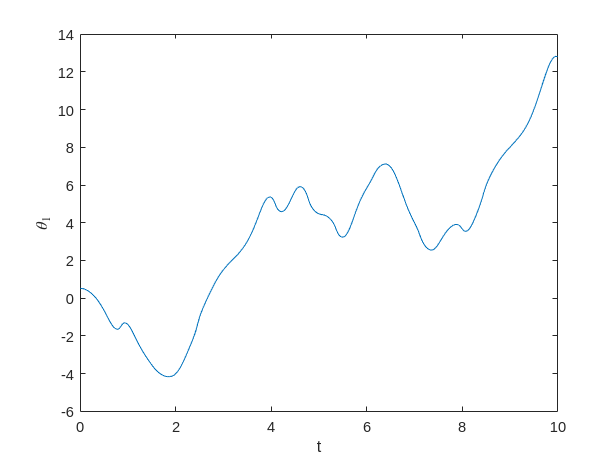

xAxisArrayXCoordinates = [-2 2];
xAxisArrayYCoordinates = [0 0];
yAxisArrayXCoordinates = [0 0];
yAxisArrayYCoordinates = [-2 2];
th = 0:pi/50:2*pi;
xunit = (bar_length(1,1) + bar_length(2,1)) * cos(th);
yunit = (bar_length(1,1) + bar_length(2,1)) * sin(th);
plot(t,state_space_matrix(:,1))
xlabel('t')
ylabel('${\theta_1}$', 'Interpreter','latex')

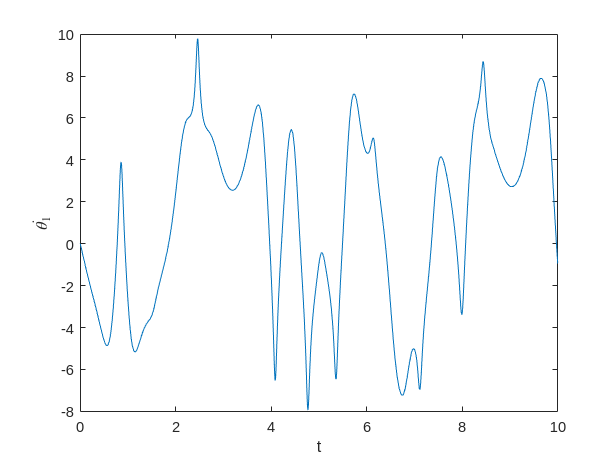

plot(t,state_space_matrix(:,2))
xlabel('t')
ylabel('$\dot{\theta_1}$', 'Interpreter','latex')

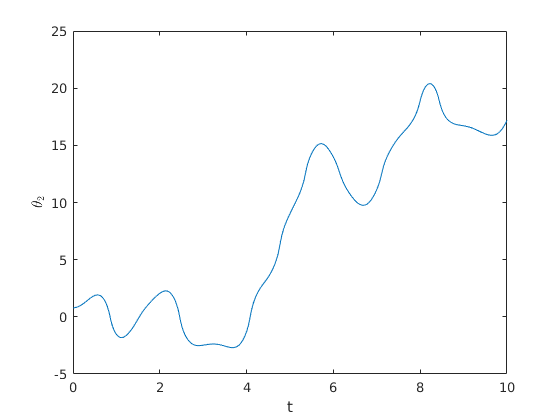

plot(t,state_space_matrix(:,3))
xlabel('t')
ylabel('${\theta_2}$', 'Interpreter','latex')

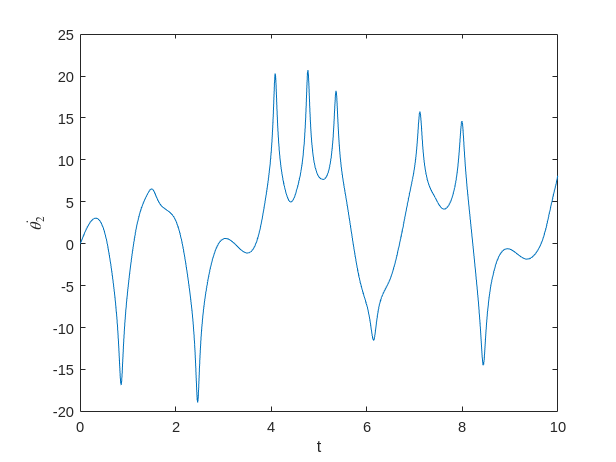

plot(t,state_space_matrix(:,4))
xlabel('t')
ylabel('$\dot{\theta_2}$', 'Interpreter','latex')

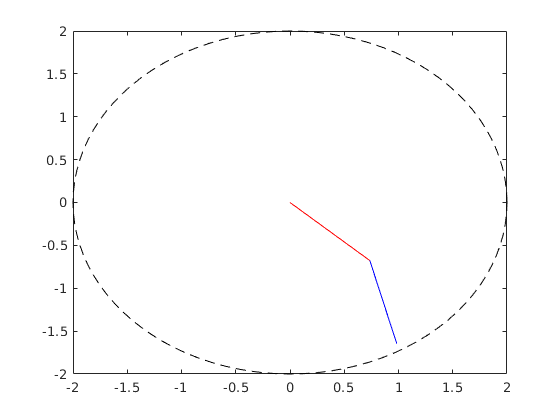


for i = 1:1:r_size(1,1)
    link1XCoordinates = [0 position(i,1)];
    link1YCoordinates = [0 position(i,2)];
    link2XCoordinates = [position(i,1) position(i,3)];
    link2YCoordinates = [position(i,2) position(i,4)];
    %Plotting Graph
    %plot(xAxisArrayXCoordinates, xAxisArrayYCoordinates,'black', yAxisArrayXCoordinates, yAxisArrayYCoordinates, 'black');% Draw rectangular axes
    plot(xunit, yunit,'k','LineStyle','--'); % Draw Circular Axes
    hold on;
    plot(link1XCoordinates, link1YCoordinates, 'red');
    plot(link2XCoordinates, link2YCoordinates, 'blue');
    pause(0.1); % pause to see realtime animation. Given in seconds
    hold off;
end